# [4.2. Биполярный транзистор](https://ru.wikipedia.org/wiki/Биполярный_транзистор)

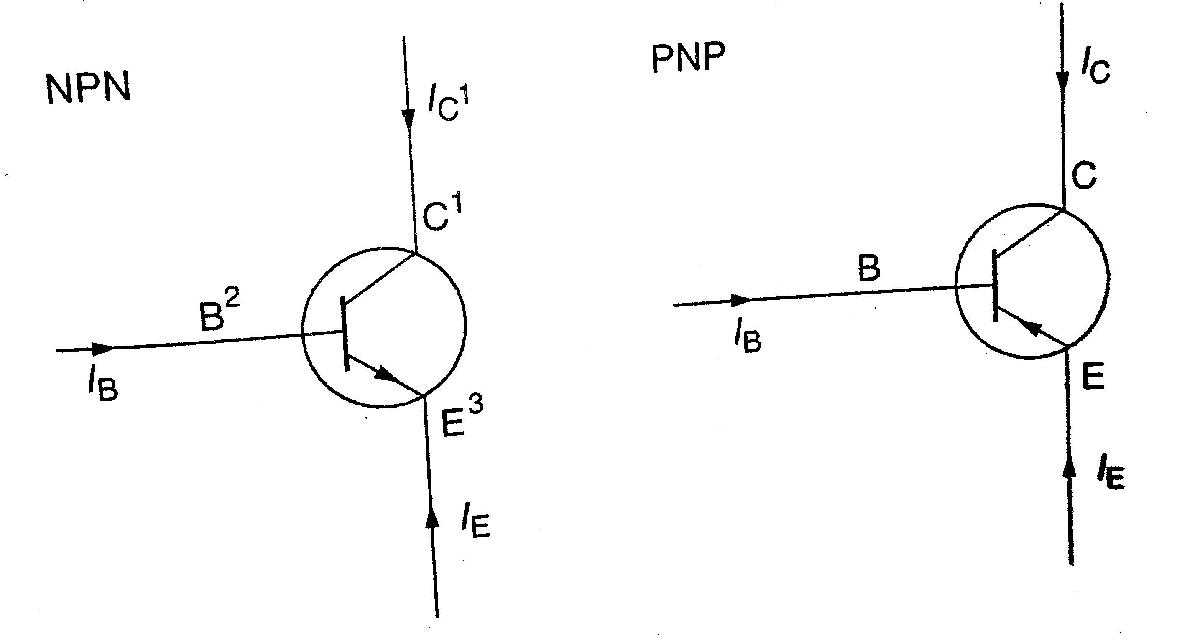

#### Низкочастотная эквивалентная цепь (схема с общим эмиттером (CE))

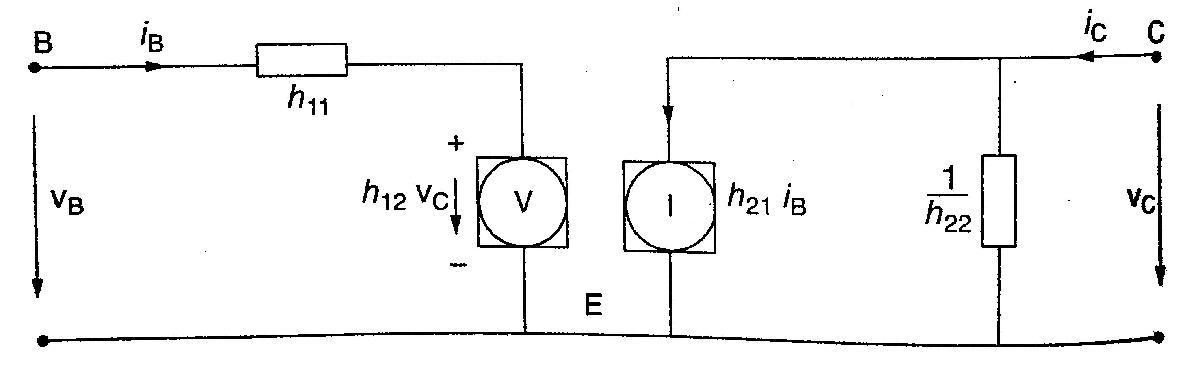

Гибридные параметры


$$h_{11} =h_{1e} =\frac{\partial }{\partial I_B }V_B |_{V_{\mathrm{CE}} } =\frac{v_B }{i_B }|_{v_C =0}$$


clear
syms h11 h_ie V_B(I_B,V_CE) v_B i_B
h11==h_ie==diff(V_B,I_B)...   % |V_CE
           ==v_B/i_B          % |V_C=0

$$ans(I\_B, V\_CE) = \left(\left(h_{11}=h_{\mathrm{ie}}\right)=\frac{\partial }{\partial I_{B}}V_{B}\left(I_{B},V_{\mathrm{CE}}\right)\right)=\frac{v_{B}}{i_{B}}$$


$$h_{12} =h_{\mathrm{re}} =\frac{\partial }{\partial V_{\mathrm{CE}} }V_B |_{I_B } =\frac{v_B }{v_C }|_{i_B =0}$$


syms h12 h_re V_B(I_B,V_CE) v_B v_C
h12==h_re==diff(V_B,V_CE)...  % |I_B
           ==v_B/v_C          % |i_B=0

$$ans(I\_B, V\_CE) = \left(\left(h_{12}=h_{\mathrm{re}}\right)=\frac{\partial }{\partial V_{\mathrm{CE}}}V_{B}\left(I_{B},V_{\mathrm{CE}}\right)\right)=\frac{v_{B}}{v_{C}}$$


$$h_{21} =h_{\mathrm{fe}} =\frac{\partial }{\partial I_B }I_C |_{V_{\mathrm{CE}} } =\frac{i_C }{i_B }|_{v_C =0}$$


syms h21 h_fe I_C(I_B,V_CE) i_C i_B
h21==h_fe==diff(I_C,I_B)...   % |V_CE
           ==i_C/i_B          % |v_C=0 

$$ans(I\_B, V\_CE) = \left(\left(h_{21}=h_{\mathrm{fe}}\right)=\frac{\partial }{\partial I_{B}}I_{C}\left(I_{B},V_{\mathrm{CE}}\right)\right)=\frac{i_{C}}{i_{B}}$$


$$h_{22} =h_{\mathrm{oe}} =\frac{\partial }{\partial V_{\mathrm{CE}} }I_C |_{I_B } =\frac{i_C }{v_C }|_{i_B =0}$$


syms h22 h_oe I_C(I_B,V_CE) i_C v_C
 h22==h_oe==diff(I_C,V_CE)... % |I_B
            ==i_C/v_C         % |i_B=0

$$ans(I\_B, V\_CE) = \left(\left(h_{22}=h_{\mathrm{oe}}\right)=\frac{\partial }{\partial V_{\mathrm{CE}}}I_{C}\left(I_{B},V_{\mathrm{CE}}\right)\right)=\frac{i_{C}}{v_{C}}$$

#### Импульсные уравнения

v_B==h11*i_B+h12*v_C,...
i_C==h22*i_B+h22*v_C

$$ans = v_{B}=h_{11}\,i_{B}+h_{12}\,v_{C}$$

$$ans = i_{C}=h_{22}\,i_{B}+h_{22}\,v_{C}$$

% Часто h12 можно пренебречь

#### Усиление по току

syms I_C alpha I_E I_CO V_CB eta V_T
I_C==-alpha*I_E+I_CO*(1-exp(V_CB/(eta*V_T)))

$$ans = I_{C}=-I_{E}\,\alpha -I_{\mathrm{CO}}\,\left({\mathrm{e}}^{\frac{V_{\mathrm{CB}}}{V_{T}\,\eta }}-1\right)$$

% alpha = коэф. усиления по току
% I_CO = обратный ток коллектор-база
% eta = фактор идеальности
syms k T e
V_T==k*T/e % = 26 мВ при комнатной температуре

$$ans = V_{T}=\frac{T\,k}{e}$$

% Знак V_CB выбирается так, чтобы в активной зоне
I_C==-alpha*I_E+I_CO

$$ans = I_{C}=I_{\mathrm{CO}}-I_{E}\,\alpha$$

#### Усиление по току в схеме CE (с общим эмиттером)

syms I_C beta I_CO I_B
I_C==(1+beta)*I_CO+beta*I_B

$$ans = I_{C}=I_{B}\,\beta +I_{\mathrm{CO}}\,\left(\beta +1\right)$$

beta==alpha/(1-alpha)

$$ans = \beta =-\frac{\alpha }{\alpha -1}$$

% Для малых токов
syms I_CB0
beta==(I_C-I_CB0)/(I_B+I_CB0)

$$ans = \beta =\frac{I_{C}-I_{\mathrm{CB0}}}{I_{B}+I_{\mathrm{CB0}}}$$

% I_CB0 = ток коллектора при I_E=0

Случай постоянного тока, если |I_B|>>|I_CB0|

syms beta_DC h_FE
beta_DC==h_FE==I_C/I_B

$$ans = \left(\beta_{\mathrm{DC}}=h_{\mathrm{FE}}\right)=\frac{I_{C}}{I_{B}}$$

Для импульсов

syms beta h_fe I_C(I_B)
beta==h_fe==diff(I_C,I_B)  % |V_CE

$$ans(I\_B) = \left(\beta =h_{\mathrm{fe}}\right)=\frac{\partial }{\partial I_{B}}I_{C}\left(I_{B}\right)$$

#### Условия насыщения

syms beta_DC I_B I_C
beta_DC*I_B>I_C

$$ans = I_{C}<I_{B}\,\beta_{\mathrm{DC}}$$

#### Тепловое сопротивление

syms T_j T_A Theta P_D
T_j-T_A==Theta*P_D

$$ans = T_{j}-T_{A}=P_{D}\,\Theta$$

% T_j = температура перехода
% T_A = температура окружающей среды
% Theta = тепловое сопротивление в градС/Вт
% P_D = мощность, рассеиваемая на кристалле